T=300

T = 300

Eg1=3.507-0.909*1e-3*T^2/(T+830)

Eg1 = 3.4346

Eg2=6.23-1.799*1e-3*T^2/(T+1462)

Eg2 = 6.1381

Eg3=Eg2*0.3+Eg1*0.7-1.3*0.3*0.7

Eg3 = 3.9727

deltaEg=Eg3-Eg1

deltaEg = 0.5381

aff=4.1-0.7*deltaEg

aff = 3.7234

deltaEc=0.7*deltaEg

deltaEc = 0.3766

deltaEv=0.3*deltaEg

deltaEv = 0.1614



k=1.3806503e-23

k = 1.3807e-23

h=6.62607015e-34

h = 6.6261e-34

% k=0.025852/300
% h=4.1356676969e-15
m0=9.10956e-31

m0 = 9.1096e-31

q=1.60217e-19;

Therma_Emssion_n=exp(-deltaEc/(k*300/q))

Therma_Emssion_n = 4.7077e-07

Therma_Emssion_p=exp(-deltaEv/(k*300/q))

Therma_Emssion_p = 0.0019


me_GaN=0.2

me_GaN = 0.2000

mh_GaN=1.0

mh_GaN = 1

% x.comp=0.3
xcomp=0.3

xcomp = 0.3000

me_AlGaN=0.314*xcomp+0.2*(1-xcomp)

me_AlGaN = 0.2342

mh_AlGaN=0.417*xcomp+1.0*(1-xcomp)

mh_AlGaN = 0.8251


cofficiten=2*(2*pi*k*m0/h^2)^1.5*1e-6

cofficiten = 4.8295e+15


Nc_GaN=(4.83e15)*(me_GaN*300)^1.5  %cm-3

Nc_GaN = 2.2448e+18

Nv_GaN=(4.83e15)*(mh_GaN*300)^1.5

Nv_GaN = 2.5097e+19


Nc_AlGaN=(4.83e15)*(me_AlGaN*300)^1.5

Nc_AlGaN = 2.8445e+18

Nv_AlGaN=(4.83e15)*(mh_AlGaN*300)^1.5

Nv_AlGaN = 1.8810e+19

Eg_GaN=3.4346

Eg_GaN = 3.4346

Eg_AlGaN=3.9727

Eg_AlGaN = 3.9727


V_surfn=110*300^2/q/Nc_GaN

V_surfn = 2.7527e+07


% 本征载流子浓度
n_i_GaN=sqrt(Nc_GaN*Nv_GaN)*exp(-Eg_GaN*q/(2*k*300))

n_i_GaN = 1.0621e-10

n_i_AlGaN=sqrt(Nc_AlGaN*Nv_AlGaN)*exp(-Eg_AlGaN*q/(2*k*300))

n_i_AlGaN = 3.1272e-15

n_i_Si=sqrt(2.8e19*1.04e19)*exp(-1.12/(2*0.025852))

n_i_Si = 6.6759e+09

%Mobility
N=0.001;
T=300;
inverse_mu=(2.61e-4)*N/(1.0e17)*(T/300)^(-1.5)*log(1+3*(T/300)^2*(N/1e17)^(-2/3))+(2.9e-4)*(T/300)^1.5+(170e-4)/(exp(1065/300)-1)

inverse_mu = 7.9276e-04

mu=1/inverse_mu

mu = 1.2614e+03


% interpolate for saturation
Vsat1=1.1459e7,Vsat2=1.1219e7;

Vsat1 = 11459000

Ec1=455.4437e3,Ec2=365.5529e3;

Ec1 = 4.5544e+05

N11=5.0264,N12=5.3193;

N11 = 5.0264

N21=1.0016,N22=1.0396;

N21 = 1.0016

AN1=2.6055,AN2=3.2332;

AN1 = 2.6055

x1=0.5,x2=0.2;

x1 = 0.5000

Vsat=(Vsat1-Vsat2)/(x1-x2)*(xcomp-x2)+Vsat2

Vsat = 11299000

Ec=(Ec1-Ec2)/(x1-x2)*(xcomp-x2)+Ec2

Ec = 3.9552e+05

N1=(N11-N12)/(x1-x2)*(xcomp-x2)+N12

N1 = 5.2217

N2=(N21-N22)/(x1-x2)*(xcomp-x2)+N22

N2 = 1.0269

AN=(AN1-AN2)/(x1-x2)*(xcomp-x2)+AN2

AN = 3.0240


% Polarization calculation(Journal of applied physics, 1999, 85(6): 3222-3233.)
a_GaN=(3.189)*10^-10 %m

a_GaN = 3.1890e-10

a_AlGaN=(-0.077*xcomp+3.189)*10^-10 %m

a_AlGaN = 3.1659e-10

% GPa
C13_GaN=103

C13_GaN = 103

C33_GaN=405

C33_GaN = 405

C13_AlGaN=5*xcomp+103

C13_AlGaN = 104.5000

C33_AlGaN=-32*xcomp+405

C33_AlGaN = 395.4000

% C/m^2
e31_GaN=-0.49

e31_GaN = -0.4900

e33_GaN=0.73

e33_GaN = 0.7300

e31_AlGaN=-0.11*xcomp-0.49

e31_AlGaN = -0.5230

e33_AlGaN=0.73*xcomp+0.73

e33_AlGaN = 0.9490

% PSP  C/m^2
Psp_GaN=-0.029

Psp_GaN = -0.0290

Psp_AlGaN=-0.052*xcomp-0.029

Psp_AlGaN = -0.0446


Ppe_AlGaN=2*(a_GaN-a_AlGaN)/a_AlGaN*(e31_AlGaN-e33_AlGaN*(C13_AlGaN/C33_AlGaN))

Ppe_AlGaN = -0.0113

sigam_AlGaN_up=0-(Psp_AlGaN+Ppe_AlGaN)

sigam_AlGaN_up = 0.0559

sigam_AlGaN_GaN=(Psp_AlGaN+Ppe_AlGaN-Psp_GaN)

sigam_AlGaN_GaN = -0.0269

ns=(-0.169+2.61*xcomp+4.5*xcomp^2)*10^13    % cm*-2

ns = 1.0190e+13

sigam_AlGaN=(Psp_AlGaN+Ppe_AlGaN)*1e-4*0.8/(1.6e-19)

sigam_AlGaN = -2.7946e+13

sigam_GaN=-Psp_GaN*1e-4*0.8/(1.6e-19)+ns

sigam_GaN = 2.4690e+13

An_GaN=4*pi*q*k^2*me_GaN*m0/h^3*1e-4

An_GaN = 24.0351

Ap_GaN=4*pi*q*k^2*mh_GaN*m0/h^3*1e-4

Ap_GaN = 120.1753

An_AlGaN=4*pi*q*k^2*me_AlGaN*m0/h^3*1e-4

An_AlGaN = 28.1451

Ap_AlGaN=4*pi*q*k^2*mh_AlGaN*m0/h^3*1e-4

Ap_AlGaN = 99.1566


(0.2342/0.2)^1.5*exp(-0.3766*q/(k*500))

ans = 2.0272e-04

exp(-1*0.3766*q/(k*300))

ans = 4.7144e-07



24*300^2/(q*Nc_GaN)

ans = 6.0058e+06

edgeNetDoping=1:1e15:1e20

edgeNetDoping = 1.0e+20 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


edgeTemp=300

edgeTemp = 300

% Albrecht
mu_inverse=2.61e-4.*edgeNetDoping./1e17.*(edgeTemp./300).^(-3/2).*log(1+3.*(edgeTemp./300).^2.*(edgeNetDoping./1e17).^(-2/3))+...
    2.9e-4*(edgeTemp/300)^(3/2)+170e-4/(exp(1065/edgeTemp)-1) 

mu_inverse =     0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


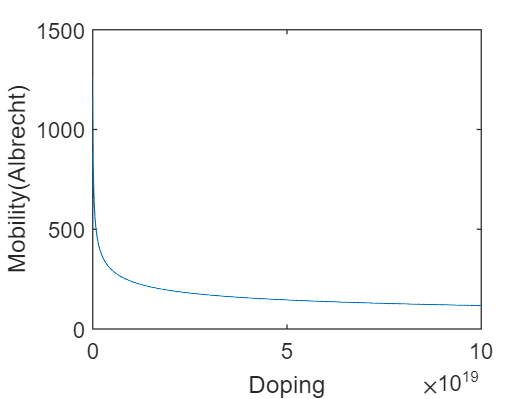

plot(edgeNetDoping,1./mu_inverse)
xlabel("Doping")
ylabel("Mobility(Albrecht)")